# Model Predictive Control - Assigment

% Clearing variables
clearvars
close all

# Problem 1 - Control Structure

## Question 1.1

The states are the masses, whih are changed by inlet and outlet mass flows. The manipulated variables are the mass flows that enter the distribution valve. The disturbance variables are the mass flows that enter the third and the fourth tank. The measured variables are the heights of the water levels in the tanks. The controlled variables are the height in tank 3 and tank 4.

## Question 1.2

Draw a block diagram to the system TODO

# Problem 2 - Deterministic and Stochastic Nonlinear Modelling

Select parameter sets that make the system minimal phase or non-minimal phase. TODO

Select operating point TODO

## Question 2.1.1

According to the mass balance equation, for a given control volume, the change of the mass in the control volume is going to be the sum of the inflows and the outflows.


$$\dot{m} = \sum_i \rho q_{i}$$


The convenience is that the volume inflows have positive and the outflows have negative signs.

The valve outflows are given by the division of the flow done by the valve, which is described by a constant. Therefore the two outflows will have the values


$$q_{out,1} = \gamma F\\
q_{out,2} = (1-\gamma) F$$


where F is one of the manipulated variables.

Outflows of the tanks are described by Bernoulli law and the inner states.


$$q=a\sqrt{2gh}, \text{where} \quad h= \frac{m}{\rho A}$$


Therefore the first order state equations can be described as


$$\frac{dm_1}{dt}=\rho \gamma_1 F_1+\rho a \sqrt{2 g \frac{m_3}{\rho A}}-\rho a \sqrt{2 g \frac{m_1}{\rho A}}$$



$$\frac{dm_2}{dt}=\rho \gamma_2 F_2+\rho a \sqrt{2 g \frac{m_4}{\rho A}}-\rho a \sqrt{2 g \frac{m_2}{\rho A}}$$



$$\frac{dm_3}{dt}=\rho (1-\gamma_2) F_2-\rho a \sqrt{2 g \frac{m_3}{\rho A}}+\rho F_3$$



$$\frac{dm_4}{dt}=\rho (1-\gamma_1) F_1-\rho a \sqrt{2 g \frac{m_4}{\rho A}}+\rho F_4$$


## Question 2.1.2

The measurement equations for the tanks are the following in the deterministic case:


$$h_i = \frac{m_i}{\rho A}$$


## Question 2.1.3

The output equations are 


$$h_1 = \frac{m_1}{\rho A}\\
h_2 = \frac{m_2}{\rho A}$$


## Question 2.2.1

This time we have the same state equations as the ones developed in Question 2.1.1, but with more information about the (deterministic) disturbances: they are piece-wise constant.


$$F_3(t) = F_{3,k} \quad \text{for} \quad t_k \leq t<t_{k+1}\\
F_4(t) = F_{4,k} \quad \text{for} \quad t_k \leq t<t_{k+1}$$


## Question 2.2.2

There is Gaussian noise on the measurement signals. It can be modelled such that


$$h_i = \frac{m_i}{\rho A}+v(t), \text{where} \quad v(t) \tilde{} N(0,R_{vv})$$


## Question 2.2.3

The output equations have not been changed with regard to the deterministic equations.

## Question 2.3.1

Having the $F_3$ and $F_4$ as Brownian motion, we can get the elements $\rho F_i dt$ in the equation of dt. This means that the differential of the state is going to be proportial to the Brownian motion $F_i \tilde{} N(F_{i,k},R_{ww})$

## Question 2.3.2

The output equations have not been changed compared to Question 2.2.2.

## Question 2.3.3

The output equations have not been changed compared to Question 2.2.3.

# Problem 3 - Nonlinear Simulation - Step Responses

Four tank system changable parameters.

% First we make an instance of the four tank system object.
fts_det = FourTankSystem;
% Choice for valve division
% NONMINIMAL PHASE TODO
gamma = [0.65; 0.55]; 
% Initial values of states
initials.m = zeros(4,1);
% Options of the solver
ODEoptions = [];

Initialization of the instance.

% Initialization of the Four Tank System object
fts_det.initialize(gamma,initials,ODEoptions);
% The steady state input signals 
ssInput  = [250; 325; 0; 0];
% The initialization guess for the steady state solution
initialGuess = [5000; 5000; 5000; 5000];  
% Calculation of the steady state
fts_det.steadyState(ssInput,initialGuess)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



## Question 3.1

First the records are deleted and initial values are set.

% Start from zero again
fts_det.reinitialize()

Simulation of the plant for different deviations from the current equilibrium input.

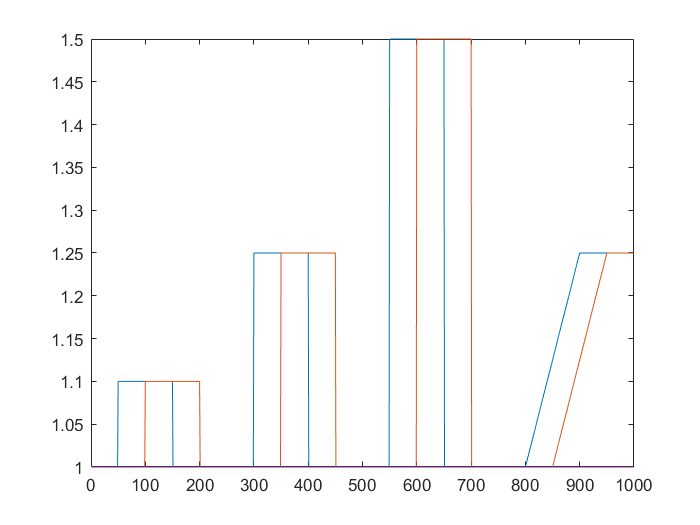

% Simulation
Ts = 1;
itmax = 1000;
t = 0:Ts:itmax*Ts;
% Deviation (from input steady state)
deviation = ones(4,length(t));
deviation(1,itmax*0.05:itmax*0.15) = 1.1;
deviation(1,itmax*0.3:itmax*0.4) = 1.25;
deviation(1,itmax*0.55:itmax*0.65) = 1.5;
deviation(1,itmax*0.8:itmax*0.9) = linspace(1,1.25,itmax*0.1+1);
deviation(1,itmax*0.9:end) = 1.25;
deviation(2,itmax*0.1:itmax*0.2) = 1.1;
deviation(2,itmax*0.35:itmax*0.45) = 1.25;
deviation(2,itmax*0.6:itmax*0.7) = 1.5;
deviation(2,itmax*0.85:itmax*0.95) = linspace(1,1.25,itmax*0.1+1);
deviation(2,itmax*0.95:end) = 1.25;
plot(deviation')
xlim([0 itmax])

for it = 1:length(t)-1
    fts_det.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
end

Now the results are plotted being nonnormalized and normalized:

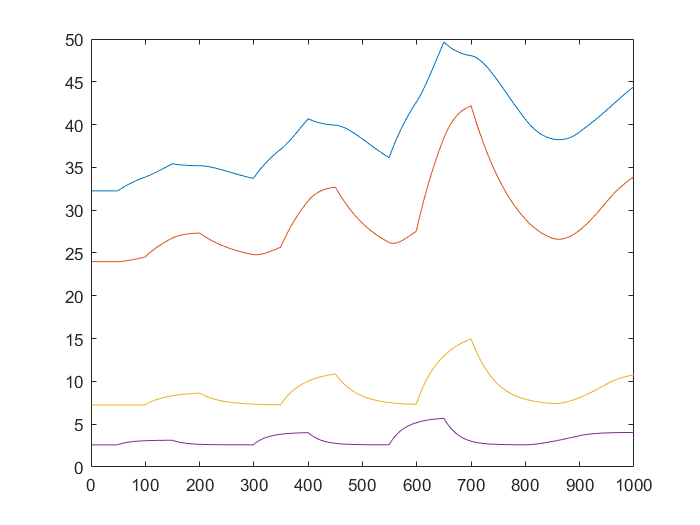

% Plot
plot(fts_det.record.meas)

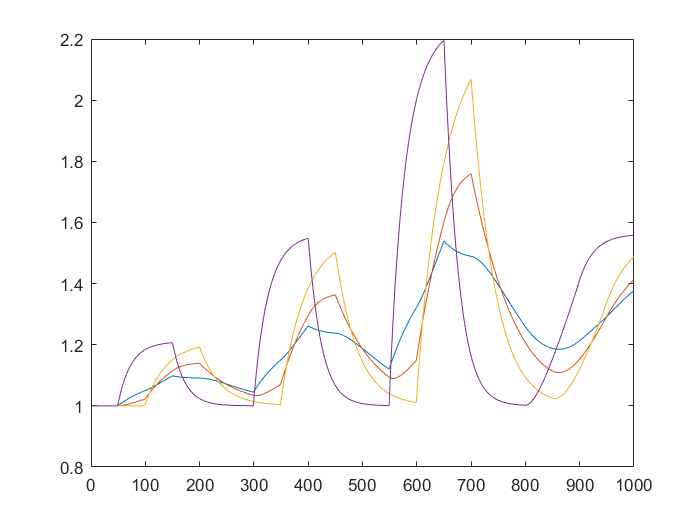

% Normalized plot
plot(fts_det.record.meas./fts_det.hs')

## Question 3.2-3

Now we duplicate the original instance to the noisy ones:

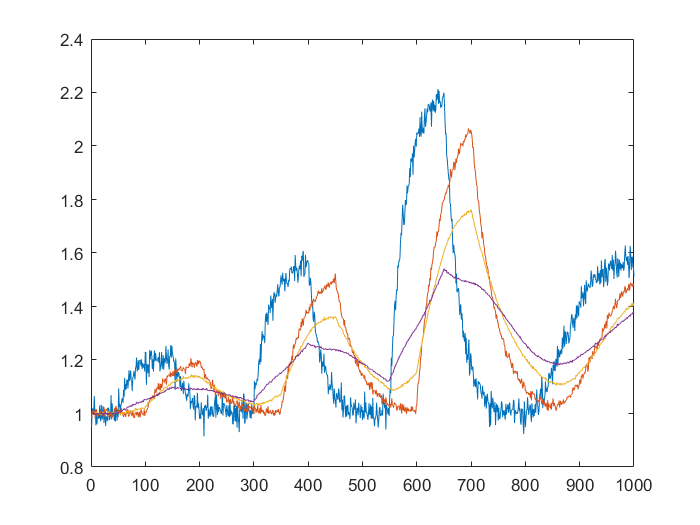

% Start from zero again
fts_det.reinitialize()
fts_vlow = copy(fts_det);
fts_vmedium = copy(fts_det);
fts_vhigh = copy(fts_det);
% Initializing the noise
noise.Rww = zeros(4);
noise.Rvv = 0.005*eye(4);
fts_vlow.addnoise(noise)
noise.Rvv = 0.02*eye(4);
fts_vmedium.addnoise(noise)
noise.Rvv = 0.1*eye(4);
fts_vhigh.addnoise(noise)
% Simulation including noise
for it = 1:length(t)-1
    fts_vlow.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
    fts_vmedium.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
    fts_vhigh.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
end
% Plots of the noise corrupted measurements:
plot(flip((fts_vlow.record.meas)./fts_vlow.hs',2))

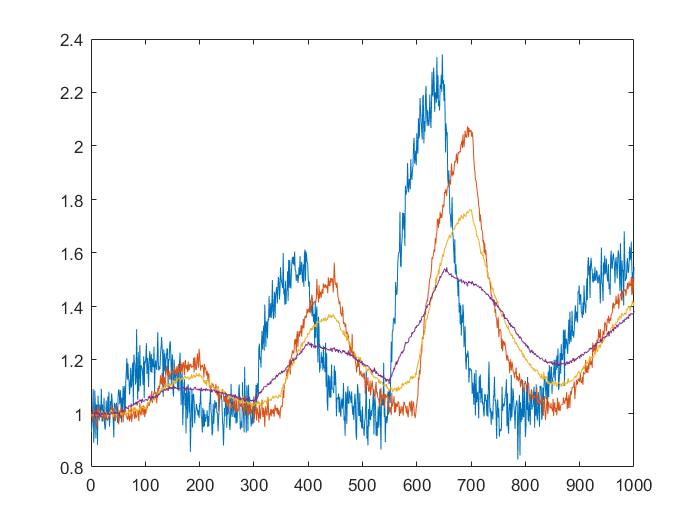

plot(flip((fts_vmedium.record.meas)./fts_vmedium.hs',2))

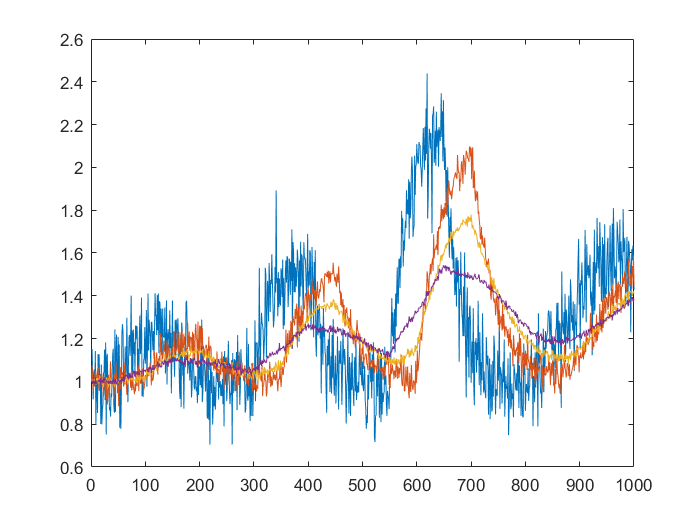

plot(flip((fts_vhigh.record.meas)./fts_vhigh.hs',2))

Note that the plots are now in opposite order to show the lines simulatenously better (this is not advantageous in colour for the whole document TODO)

## Question 3.5-8 TODO

# Problem 4 - Linearization and discretization

## Question 4.1

The continuous time linearized state space models for the three models from Problem 2: for all the models TODO

% Create the object with noisy disturbance
fts = copy(fts_det);

Only the last two states are corrupted by noise.

% Noises
noise.Rww = diag([0 0 10 10]);
noise.Rvv = 0.02*eye(4);
fts.addnoise(noise)
% Analytically linearize the system
fts.linearize
% Plot the system matrices
fts.ssc

ans = struct with fields:
      A: [4×4 double]
      B: [4×2 double]
      C: [2×4 double]
     Cz: [2×4 double]
    Rww: [4×4 double]
    Rvv: [4×4 double]
    Rwv: [4×4 double]


## Question 4.2 TODO

The zero-pole-gain form transfer functions are the following:

% Zero-pole-gain form of the continuous transfer function
zpk(fts.tfc)


ans =
 
  From input 1 to output...
        0.0017099
   1:  -----------
       (s+0.01259)
 
             4.0897e-05
   2:  ----------------------
       (s+0.04442) (s+0.0146)
 
  From input 2 to output...
             3.1459e-05
   1:  -----------------------
       (s+0.02657) (s+0.01259)
 
       0.0014469
   2:  ----------
       (s+0.0146)
 
Continuous-time zero/pole/gain model.



We can see that certain poles appear in more transfer functions. Since leading the fluid through one extra tank just gives extra dynamics but does not change the earlier, the dynamics leading to the same measurements share poles for different inputs.

## Question 4.3

The general (polynomial) form of the continuous transfer functions are the following:

% Polynomial forms of the continuous transfer functions
fts.tfc


ans =
 
  From input 1 to output...
         0.00171
   1:  -----------
       s + 0.01259
 
                4.09e-05
   2:  ---------------------------
       s^2 + 0.05902 s + 0.0006484
 
  From input 2 to output...
                3.146e-05
   1:  ---------------------------
       s^2 + 0.03916 s + 0.0003345
 
        0.001447
   2:  ----------
       s + 0.0146
 
Continuous-time transfer function.



## Question 4.4

Compare to the identification from Problem 3 TODO

## Question 4.5

For an easy interpretation choice, the chosen sampling time is 1 second. In this case, the discrete state space model is:

% Chosen sampling time
Ts = 1;
% Discretization
fts.discretize(Ts)

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

Error in c2d_noise (line 3)
M = [-A' G*G'; zeros(nx,nx) A];

Error in FourTankSystem/discretize (line 132)
                System.Rww = c2d_noise(fts.A,fts.Lrww,Ts);

% Converting the state space system to discrete
fts.ssd

## Question 4.6-7 TODO

Since the code for calculating the Markov parameters is embedded into a Kalman filter object, we are going to first initialize the Kalman filter.

% system.A = A;
% system.B = B;
% system.C = C;
% system.Cz = Cz;
% system.G = G;
% noise.R = Rvv;
% noise.Q = 1;
% noise.S = Rwv;
% initial.x = zeros(3,1);
% initial.P = eye(3);
% kfType = 'stationary';
% kf = KalmanFilter;
horizon = 10;
kf.initialize(system,noise,initial,kfType,horizon);

# Problem 5

## Question 5.1

Is it a theoretical problems? TODO, connect with results of identification

If we do not significantly deviate from the chosen linearisation point, the error that we commit during estimation is negligible (this is the basic motivation of using Taylor series).

If we have a constant sampling time, then the way of connecting the instants of a linear system is multiplying by $e^{A(t-t_0)}=e^{AT_s}=A_d$, and $B_d$ can be deduced from


$$\pmatrix{A_d & B_d \cr 0 & I} = \exp{\pmatrix{A & B \cr 0 & 0}T_s}$$


## Question 5.2